## El método de Hardy - Cross

Es el procedimiento más utilizado para determinar los caudales circulantes en una red reticulada cuyos diámetros son conocido, se puede resolver un sistema como el que se encuentra a continuación:

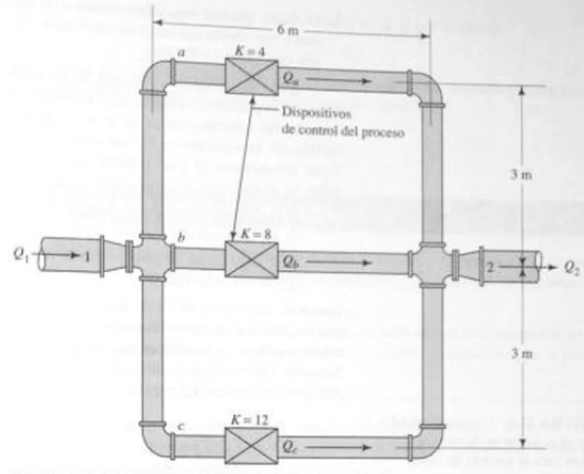

**Figura 1.** Esquema de la ramificaciones para aplicar el método de Cross.([Moth, 2008](https://avdiaz.wordpress.com/wp-content/uploads/2008/10/fluidos-mott-6ed.pdf)).

### PASOS A SEGUIR:

- Se asume la dirección del flujo.

- Se asume un flujo para cada circuito.

- Se define los circuitos.

- Se dá un signo según la dirección del flujo, en sentido horario o antihorario.

- Se resuelve siguiendo los pasos que se registran en el código.

### ECUACIONES A USAR:


$$A=\frac{{\pi \oslash }^2 }{4}$$



$$\mathrm{Re}=\frac{v*\oslash *\rho }{\mu }$$



$$h_{\mathrm{sistema}} =\frac{1}{2}\left(\frac{\mathrm{fd}*L}{\oslash }+\sum_{K=1}^n k_{\mathrm{acc}} \right)*\frac{1}{\frac{\pi^2 }{16}*\oslash^4 }*\overset{\ldotp }{Q^2 }$$



$$\alpha =\frac{1}{2}\left(\frac{\mathrm{fd}*L}{\oslash }+\sum_{K=1}^n k_{\mathrm{acc}} \right)*\frac{1}{\frac{\pi^2 }{16}*\oslash^4 }\;$$



$$\Delta Q=\frac{\sum h_{\mathrm{sistema}} }{\sum 2\alpha \overset{\cdot }{Q} }$$



$${\overset{\ldotp }{Q} }_{\mathrm{nuevo}} ={\overset{\ldotp }{Q} }_{\mathrm{antiguo}} -\Delta Q\;$$



$$%\overset{\cdot }{Q} =\frac{\Delta Q}{{\overset{\ldotp }{Q} }_{\mathrm{antiguo}} }$$


### CONSIDERACIONES PARA ASUMIR EL FLUJO:


$$a>\oslash \;\mathrm{se}\;\mathrm{tiente}>\overset{\ldotp }{Q}$$



$$a<L\;\textrm{se}\;\textrm{tiente}>\overset{\ldotp }{Q}$$



$$a<K\;\mathrm{se}\;\mathrm{tiente}>\overset{\ldotp }{Q}$$


### RESUMEN RÁPIDO DE LAS VARIABLES QUE SE CALCULAN

- 
$${\overset{\ldotp }{Q} }_i$$


- 
$$V_i$$


- 
$$\mathrm{Re}$$


- $f_D$ (Se debe ingresar revisando la gráfica)

- 
$$h_{\mathrm{fA}}$$


- 
$${\overset{\ldotp }{2\alpha Q} }_i$$


- 
$${\overset{\ldotp }{\Delta Q} }_i$$


- 
$${\overset{\ldotp }{Q} }_{\mathrm{nuevo}}$$


- 
$$%\overset{\cdot }{Q}$$


## COMO SE DEBE DESPLEGAR:

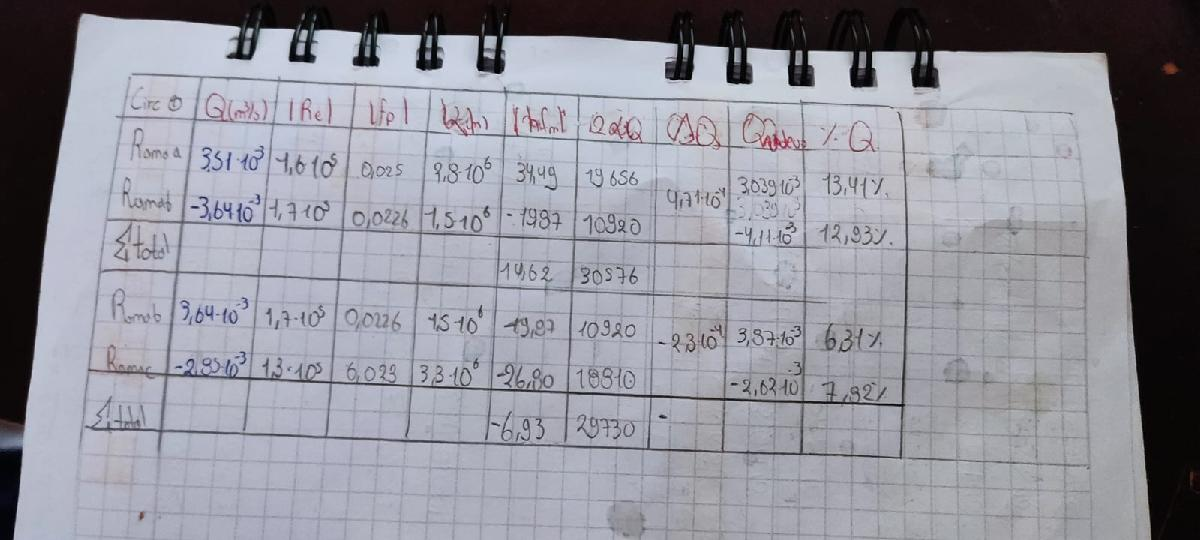

**Figura 2. **Imagen de la tabla de referencia que se debe desplegar al final del código(Yépez,2024).

## Gráficas y tablas que se usan en el código:

Considerar usar la siguiente tabla para ingresar la suma de los accesorios que se tienen en las ramificaciónes de la tubería.

## 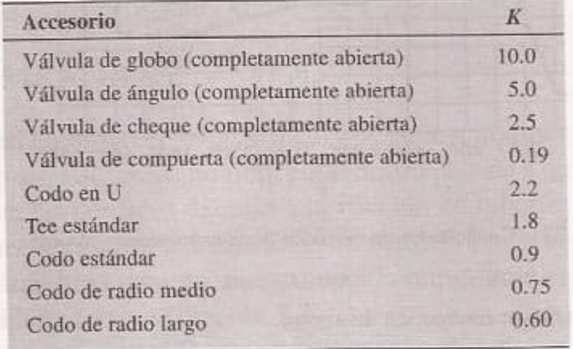

**Figura 3.** Gráfica para los accesorios ([Moth,2008](https://avdiaz.wordpress.com/wp-content/uploads/2008/10/fluidos-mott-6ed.pdf)).

Considerar usar la siguiente tabla para ingresar el fd.

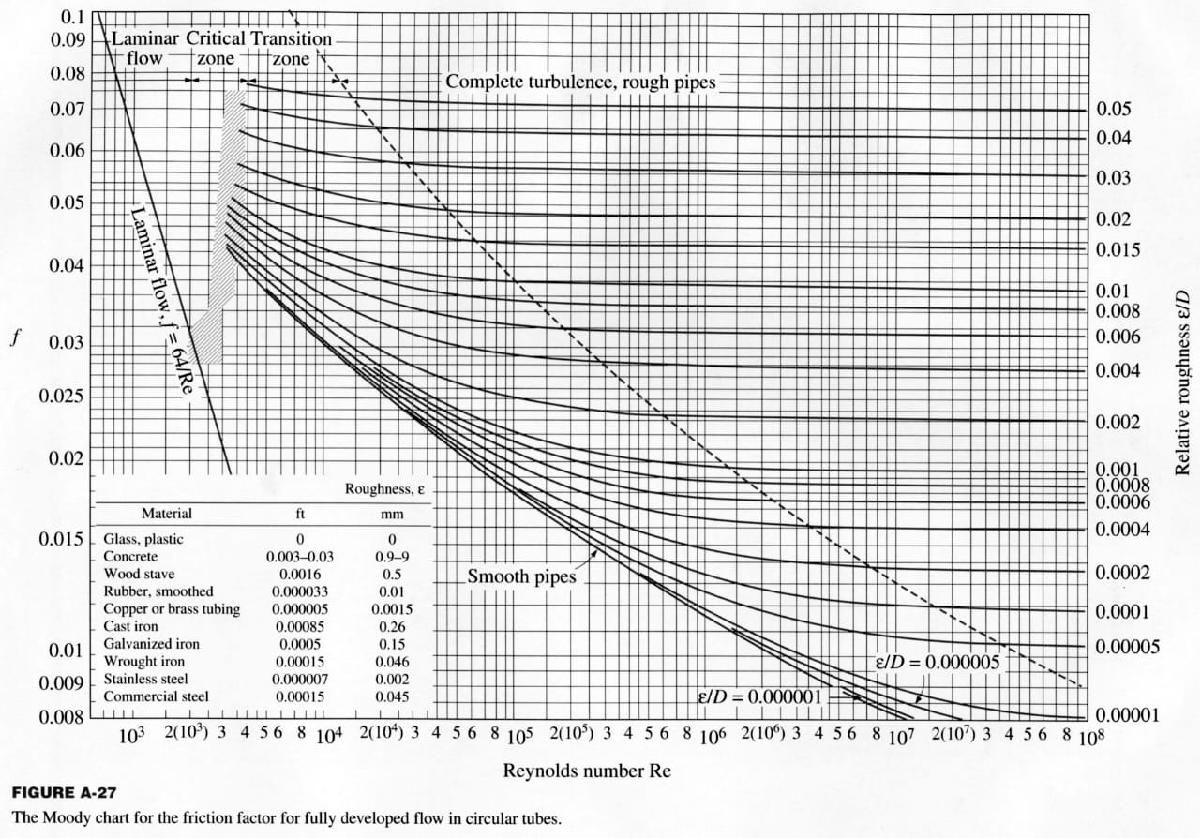

**Figura 4.** Gráfica para colocar el factor de Darcy [(Moth,2008)](https://avdiaz.wordpress.com/wp-content/uploads/2008/10/fluidos-mott-6ed.pdf)

## INGRESO DE DATOS

## Ingreso de propiedades del fluido

clc, clear
d = input("Ingrese la desnidad del fluido en kg/m^3: ");
u = input("Ingrese la viscosidad del fluido en pa*s: ");

## Ingreso datos para la iteración 

n = input("Ingrese el número de ramificaciones para trabajar: ");
%Para los diámetros:
Diametros = IngresoDatos(n,"Diametro en m");
%Para las longitudes
longitudes = IngresoDatos(n,"Longitud en m");
%Para los accesorios
kacc = IngresoDatos(n,"Suma de Kacc");%Revisar la Figura 3 para ingresar la suma de los valores 
% Cálculo la rugosidad relativa para cada ramma
rugosidad = menu("Seleccione el tipo de material","Vidrio, plástico","Concreto","Madera","Goma","Cobre o tubo de latón","Hierro fundido","Hierro galvanizado","Hierro forjado","Acero inoxidable","Acero comercial");
switch rugosidad
    case 1
        rugosidad = 0; %La rugosidad está en mm
    case 2
         rugosidad = 4.5;
    case 3
         rugosidad = 0.5;
    case 4
         rugosidad= 0.01;
    case 5
         rugosidad = 0.0015;
    case 6
         rugosidad = 0.26;
    case 7
         rugosidad = 0.15;
    case 8
         rugosidad = 0.046;
    case 9
         rugosidad = 0.002;
    case 10
         rugosidad = 0.045;
end

## Condiciones iniciales / Cálculo de caudales iniciales

QT = input("Ingrese el caudal total en m^3/s: ");
Q = ones(1,n)';
Dmax = max(Diametros);
Dmin = min(Diametros);
Lmax = max(longitudes);
Lmin = min(longitudes);
kaccmax = max(kacc);
kaccmin = min(kacc);
%Para los diámetros
if Diametros(1)~= Diametros(2) && Diametros(1)~= Diametros(3) && Diametros(2)~= Diametros(3)
 for i = 1:n
    if Diametros(i) == Dmax 
        Q(i) = 0.6*QT;
    elseif Diametros(i) == Dmin 
        Q(i) = 0.1*QT;
    else
        Q(i) = 0.3*QT;
    end
 end
elseif longitudes(1)~= longitudes(2) && longitudes(1)~= longitudes(3) && longitudes(2)~= longitudes(3)
%Para las longitudes
 for i = 1:n
    if longitudes(i) == Lmax 
        Q(i) = 0.1*QT;
    elseif longitudes(i) == Lmin 
        Q(i) = 0.6*QT;
    else
        Q(i) = 0.3*QT;
    end
 end
%Para los accesorios 
elseif kacc(1)~= kacc(2) && kacc(1)~= kacc(3) && kacc(2)~= kacc(3)
 for i = 1:n
    if kacc(i) == kaccmax 
        Q(i) = 0.1*QT;
    elseif kacc(i) == kaccmin 
        Q(i) = 0.6*QT;
    else 
        Q(i) = 0.3*QT;
    end
 end
end

## PREPARACIÓN PARA ITERAR

%DATOS PARA USARLOS COMO EJEMPLO PARA 3 RAMIFICACIONES SI SE DESEA USAR COMENTAR TODA LA LÍNEA DE
%CÓDIGO A EXCEPCIÓN DE LA LÍNEA 12 - 34
% n = 3;
% Diametros = [0.026 0.026 0.026 ];
% longitudes = [8 4 8];
% kacc = [8 6 12];
% QT = 0.0103;
% Q = [3.3e-3 5.33e-3 1.67e-3];
% d = 1000;
% u = 1e-3;
%DATOS PARA USARLOS COMO EJEMPLO PARA 4 RAMIFICACIONES; 
% n = 4;
% Diametros = [0.026 0.026 0.026 0.026 ];
% longitudes = [8 4 4 8 ];
% kacc = [8 6 12 20];
% QT = 0.0103;
% Q = [4.12e-3 3.09e-3 2.06e-3 1.03e-3 ];
% d = 1000;
% u = 1e-3;

## PROCESO ITERATIVO PARA 3 CAUDALES

sumapocentajeQ = 5; %Valor inicial supuesto para que entre en el lazo while
while sumapocentajeQ >= 3.5
%Arreglo de datos para comenzar con el proceso
Diterativo = arreglomas(Diametros,n);
Literativo = arreglomas(longitudes,n);
Kiterativo = arreglomas(kacc,n);
Qiterativo = arreglomas(Q,n);
Qiterativo2 = arreglomenos(Q,n);
%Cálculo la rugosidad relativa para cada rama
rugosidaditerartivo = arreglomas(rugosidad./1000 * ones(1,n)',n);
rugosidadrelativaiterativo = rugosidaditerartivo ./ Diterativo;
%%Calculo Re
Re = d./(u*(pi./4))*(Qiterativo ./ Diterativo);
%%Calculo del Fd
Tabla = table(Re,rugosidadrelativaiterativo)
Fd1 = IngresoDatos(n,"El factor de darcy"); %Se puede hacer una lectura del Fd, se usa la Figura 4 se debe ingresar tantos factores de darcy como ramificaciones exista.
Fd = arreglomas(Fd1,n);
%%Cálculo de alfa
alfaierativo = ((((Fd .* (Literativo ./ Diterativo)) + Kiterativo) ./ (Diterativo.^4)) * (8 / pi.^2))/10;
%%Cálculo de pérdidas
Perdidasiterativo = alfaierativo.*(Qiterativo.^2);
%Proceso para colocar signo
vectorneg = 1:length(Perdidasiterativo);
c = vectorneg(2:2:end);
for i = c
    Perdidasiterativo(i) = -Perdidasiterativo(i);
end
sumatotPerdidasiterativo = Sumavalores(Perdidasiterativo);
%%Cálculo de 2alfaQ
twoalfaQiterativo = (2*alfaierativo.*Qiterativo);
sumatottwoalfaQiterativo = Sumavalores(twoalfaQiterativo);
%%Cálculo de DeltaQ
DeltaQ = sumatotPerdidasiterativo ./ sumatottwoalfaQiterativo;
%%Cálculo Q nuevo Este proceso es valido solo para 3 ramificaciones.
Qnuevo = ones(1,n)';
Qnuevo(1) = Qiterativo2(1) - DeltaQ(1);
Qnuevo(end) = Qiterativo2(end) - DeltaQ(end);
Qnuevo = abs(Qnuevo);
Qnuevo(2) = QT - Qnuevo(1) - Qnuevo(end);
Q = Qnuevo;
%Cálculo %Q (error)
PorcentajeQ = (abs(DeltaQ) ./ Qiterativo)*100;
sumapocentajeQ = sum(PorcentajeQ);
end
MatrizFinal = table(Qiterativo2,Re,Fd,alfaierativo,Perdidasiterativo,twoalfaQiterativo,DeltaQ,PorcentajeQ);%Tabla Final
MatrizFinal.Properties.VariableNames = ["Q [m^3/s]" "Re" "fd" "α" "hf" "2*α*Q" "ΔQ" "%Q"]
